# Team 3: Hexapod Robot Leg Dynamics

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

The hexapod robot can initially be lookoed at as each leg being it's own RRR type robot which we can build the dynamic model for in two ways. The first is to build everything out by hand as taught in our Dynamics and Controls classes using the lagrangian method. The second method is to utilize the tools we have available in MATLAB with the Robotics System Toolbox.

### The Basics

We know that we want our robot to have a three revolute joints and would have a basic diagram as shown in Fig. 1.

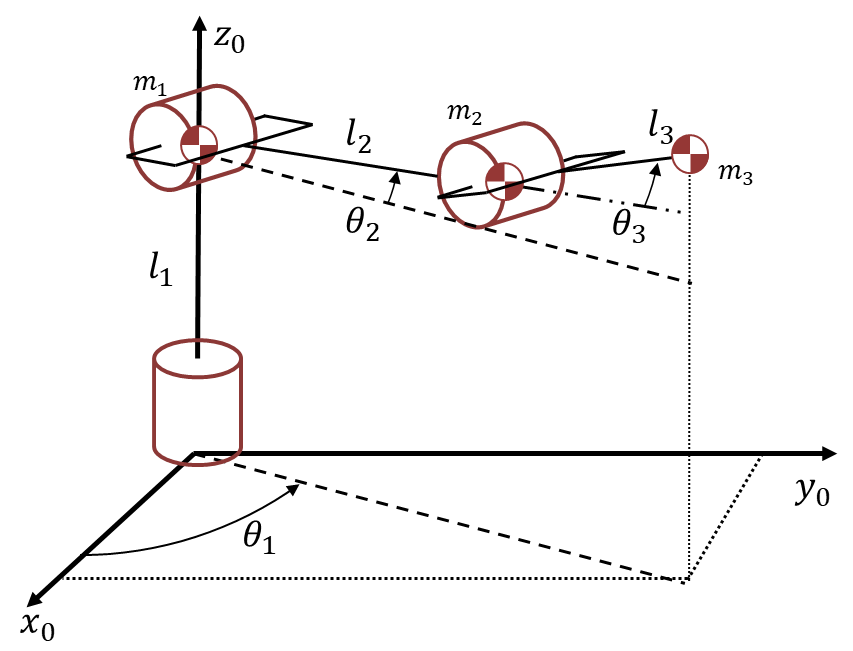

**Figure 1: RRR Robot layout model.**

From this layout we can also easily determine our Denavit-Hartenberg (DH) parameters as shown in Table 1.

**Table 1: RRR Robot DH parameters.**

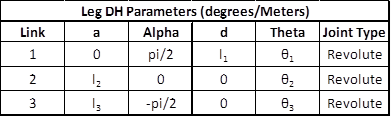

Now we can work on our models.

*Note: All values are in meters, radians, and kilograms.*

### Lagrangian Method

This method has some simplifications in it such that it assumes the links are massless and we only have point masses at the end of the links. This is not ideal as there would be no associated rotational kinetic energy when moving, and could over estimate the torque needed by each motor as the point mass is further away than the actual Center of Mass. This model will provide us with insight and hopefully the shortcomings of this model are removed when we move the the Rigid Body Tree Model next.

First, we should remove items from workspace, freeing up system memory, and clear current command window

clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

#### Setting Veriables

%sympref('FloatingPointOutput',false);

syms m1 m2 m3 ... % Mass of actuator and tip load
q1 q2 q3... % Joint variables
l1 l2 l3 ... % Link Lengths
dq1 dq2 dq3 ... % Velocities
ddq1 ddq2 ddq3 ... % Accelerations
t g real; % Time and gravity

a1 = 0;
a2 = l2;
a3 = l3;

alpha1 = pi/2;
alpha2 = 0;
alpha3 = -pi/2;

d1 = l1;
d2 = 0;
d3 = 0;

theta1 = q1;
theta2 = q2;
theta3 = q3;

dhparams = [a1 alpha1 d1 q1;
    a2 alpha2 d2 q2;
    a3 alpha3 d3 q3];

#### Creating joint positions from DH/Kinematic model

We can now get the transformation matrices defining each link with respect to the previous link

T01 = DHparameters(dhparams(1,:)); % Tip of Link 1/ Base of Link 2
T12 = DHparameters(dhparams(2,:));
T23 = DHparameters(dhparams(3,:));

T2 = T01*T12; % Tip of Link 2/ Base of Link 3
T3 = T2*T23; % Tip of Link 3/ Tool

Link1_CoM_full = T01*[-0.0001; -0.0242; 0.0061; 1]; % This is correct !!!! DO NOT CHANGE !!!
Link1_CoM = Link1_CoM_full(1:3);
Link1 = T01(1:3,4); % Link 1 Tip

Link2_CoM_full = T2*[-0.3739; 0.0089; 0.0003; 1];
Link2_CoM = Link2_CoM_full(1:3);
Link2 = T2(1:3,4); % Link 2 Tip

Link3_CoM_full = T3*[-0.6529; 0.0041; 0.0047; 1];
Link3_CoM = Link3_CoM_full(1:3);
Link3 = T3(1:3,4); % Link 3 Tip


Plotting the links and joints to verify that we have the correct DH parameter asssignment. For this, $l_1$, $l_2$, and $l_3$ were given arbetrary values to show a similar layout as displayed in Fig. 1.

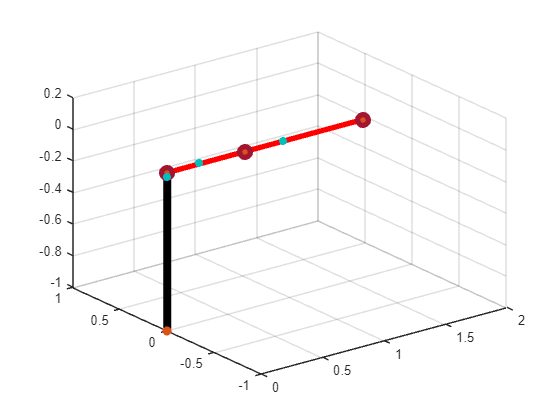

plot3([0 0],[0 0],[-1 0],'-ko','LineWidth',6,'MarkerEdgeColor','#D95319','MarkerFaceColor','g','MarkerSize',1);
grid on;
hold on;
t = [0 0 0];
T1_temp = subs(T2, [l1 l2 l3 q1 q2 q3], [0 .640 .960 t(1) t(2) t(3)]);
T2_temp = subs(T3, [l1 l2 l3 q1 q2 q3], [0 .640 .960 t(1) t(2) t(3)]);
Link1_CoM_temp = subs(Link1_CoM, [l1 l2 l3 q1 q2 q3], [0 .640 .960 t(1) t(2) t(3)]);
Link2_CoM_temp = subs(Link2_CoM, [l1 l2 l3 q1 q2 q3], [0 .640 .960 t(1) t(2) t(3)]);
Link3_CoM_temp = subs(Link3_CoM, [l1 l2 l3 q1 q2 q3], [0 .640 .960 t(1) t(2) t(3)]);
x = [0 T1_temp(1,4) T2_temp(1,4)];
y = [0 T1_temp(2,4) T2_temp(2,4)];
z = [0 T1_temp(3,4) T2_temp(3,4)];
plot3(x,y,z,'-ro','LineWidth',4,'MarkerEdgeColor','#A2142F','MarkerFaceColor','#D95319','MarkerSize',8);
scatter3(Link1_CoM_temp(1),0,Link1_CoM_temp(3),'filled','MarkerFaceColor',[0 .75 .75])
scatter3(Link2_CoM_temp(1),0,Link2_CoM_temp(3),'filled','MarkerFaceColor',[0 .75 .75])
scatter3(Link3_CoM_temp(1),0,Link3_CoM_temp(3),'filled','MarkerFaceColor',[0 .75 .75])

#### Define State Variables

q = [q1; q2; q3];
dq = [dq1; dq2; dq3];
ddq = [ddq1; ddq2; ddq3];

#### Compute Velocities

V1 = compute_velocity(Link1_CoM, q, dq)

$$V1 = \left(\begin{array}{c} \frac{{\mathrm{dq}}_{1}\,\left(61\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\right)}{10000}\\ -\frac{{\mathrm{dq}}_{1}\,\left(\cos\left(q_{1}\right)-61\,\sin\left(q_{1}\right)\right)}{10000}\\ 0 \end{array}\right)$$

V2 = compute_velocity(Link2_CoM, q, dq)

$$V2 = \left(\begin{array}{c} \frac{3\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)}{10000}-\frac{89\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{10000}+\frac{3739\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{10000}+\frac{3739\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{10000}+\frac{89\,{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{10000}-{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \frac{3\,{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)}{10000}-\frac{3739\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{10000}-\frac{89\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{10000}-\frac{89\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{10000}+\frac{3739\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{10000}+{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\frac{{\mathrm{dq}}_{2}\,\left(3739\,\cos\left(q_{2}\right)+89\,\sin\left(q_{2}\right)-10000\,l_{2}\,\cos\left(q_{2}\right)\right)}{10000} \end{array}\right)$$

V3 = compute_velocity(Link3_CoM, q, dq)

#### Kinetic and Potential Energies

KE1 = simplify(expand(0.5*m1*(V1')*V1));
KE2 = simplify(expand(0.5*m2*(V2')*V2));
KE3 = simplify(expand(0.5*m3*(V3')*V3));
PE1 = m1*g*Link1_CoM(3);
PE2 = m2*g*Link2_CoM(3);
PE3 = m3*g*Link3_CoM(3);
KE = KE1 + KE2 + KE3;
PE = PE1 + PE2 + PE3;
KE = simplify(expand(KE))

PE = simplify(expand(PE))

$$PE = \frac{g\,\left(10000\,l_{1}\,m_{1}-242\,m_{1}+10000\,l_{1}\,m_{2}+10000\,l_{1}\,m_{3}+47\,m_{3}\,\cos\left(q_{2}+q_{3}\right)-6529\,m_{3}\,\sin\left(q_{2}+q_{3}\right)+89\,m_{2}\,\cos\left(q_{2}\right)-3739\,m_{2}\,\sin\left(q_{2}\right)+10000\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)+10000\,l_{2}\,m_{3}\,\sin\left(q_{2}\right)+10000\,l_{3}\,m_{3}\,\sin\left(q_{2}+q_{3}\right)\right)}{10000}$$

#### Calculate Lagrangian

L = simplify(expand(KE - PE))

#### Calculate Torque

dl_dq = derivative(L,q);
dl_ddq = derivative(L,dq);
dl_ddqdt = compute_velocity(dl_ddq,dq,ddq);
jointau = dl_ddqdt - dl_dq';
jointau = simplify(expand(jointau))

#### Find Compact Form

We find the inertia matrix by taking the corresponding ddq value "out of" the tau expression. For example, for M11, we find the part of tau(1) that is multiplied by ddq1 by replacing ddq1 with 0, subtracting the result from the original tau and dividing by ddq1. For M12, we use tau(1) and ddq1. For M21, we use tau(2) and ddq1, etc.

M11 = simplify((jointau(1) - subs(jointau(1),ddq(1),0))/ddq(1));
M12 = simplify((jointau(1) - subs(jointau(1),ddq(2),0))/ddq(2));
M13 = simplify((jointau(1) - subs(jointau(1),ddq(3),0))/ddq(3));
M21 = simplify((jointau(2) - subs(jointau(2),ddq(1),0))/ddq(1));
M22 = simplify((jointau(2) - subs(jointau(2),ddq(2),0))/ddq(2));
M23 = simplify((jointau(2) - subs(jointau(2),ddq(3),0))/ddq(3));
M31 = simplify((jointau(3) - subs(jointau(3),ddq(1),0))/ddq(1));
M32 = simplify((jointau(3) - subs(jointau(3),ddq(2),0))/ddq(2));
M33 = simplify((jointau(3) - subs(jointau(3),ddq(3),0))/ddq(3));
M = [M11 M12 M13;
M21 M22 M23;
M31 M23 M33];
M = simplify(expand(M))

%The gravity matrix is all terms not multiplied by dq or ddq.
G = subs(jointau, {ddq(1),ddq(2),ddq(3),dq(1),dq(2),dq(3)},{0,0,0,0,0,0})

$$G = \left(\begin{array}{c} 0\\ g\,l_{3}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)-\frac{89\,g\,m_{2}\,\sin\left(q_{2}\right)}{10000}-\frac{6529\,g\,m_{3}\,\cos\left(q_{2}+q_{3}\right)}{10000}-\frac{47\,g\,m_{3}\,\sin\left(q_{2}+q_{3}\right)}{10000}-\frac{3739\,g\,m_{2}\,\cos\left(q_{2}\right)}{10000}+g\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)+g\,l_{2}\,m_{3}\,\cos\left(q_{2}\right)\\ -\frac{m_{3}\,\left(65290000\,g\,\cos\left(q_{2}+q_{3}\right)+470000\,g\,\sin\left(q_{2}+q_{3}\right)-100000000\,g\,l_{3}\,\cos\left(q_{2}+q_{3}\right)\right)}{100000000} \end{array}\right)$$

%The coriolis/centripetal coupling vector is the result of subtracting the
%inertia and gravity portions from tau.
C1 = simplify(expand(jointau(1) - M(1,:)*[ddq1 ddq2 ddq3].' - G(1)));
C2 = simplify(expand(jointau(2) - M(2,:)*[ddq1 ddq2 ddq3].' - G(2)));
C3 = simplify(expand(jointau(3) - M(3,:)*[ddq1 ddq2 ddq3].' - G(3)));
C = [C1;C2;C3]

### Rigid Body Tree Model

Setting inital veriables and loop to be able to build each leg ratio as its own robot and get the worst case (full radial extension of the leg) torque of each joint for that specific let link length ratio.

joints_tau_max = zeros(6,3); % Precreating the size of the matrix to store the joint torques
joints_tau_typical = zeros(6,3);

Data for each ratio will be stored in the ratioTau variable will be assigned as shown


$$\textrm{joints}\_\textrm{tau}=\left\lbrack \begin{array}{ccc}
\textrm{Ratio1}\_\textrm{Joint1} & \cdots  & \textrm{Ratio1}\_\textrm{Joint3}\\
\vdots  & \ddots  & \vdots \\
\textrm{RatioN}\_\textrm{Joint1} & \cdots  & \textrm{RatioN}\_\textrm{Joint3}
\end{array}\right\rbrack$$


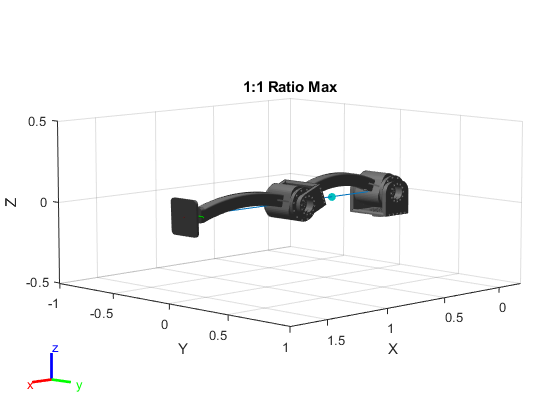

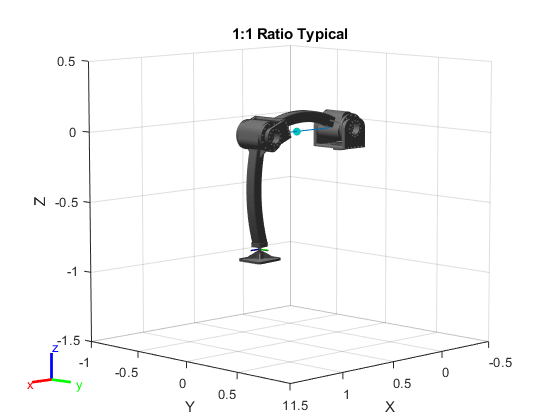

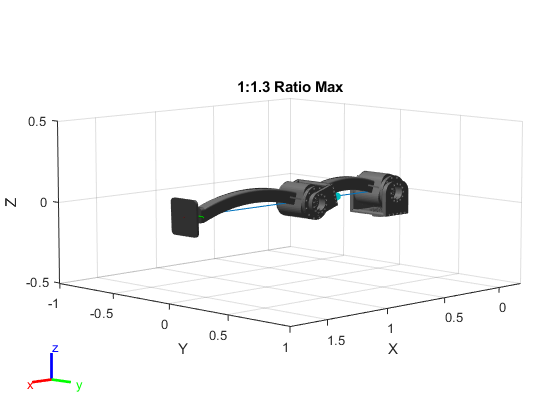

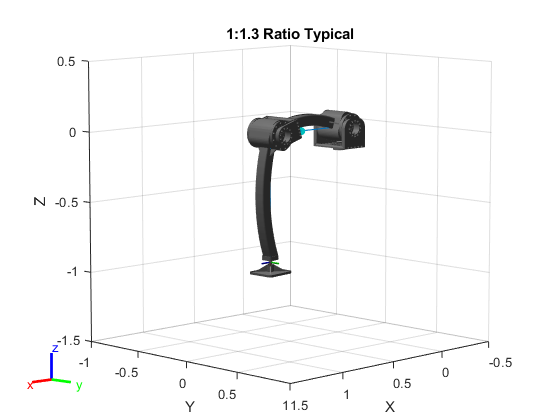

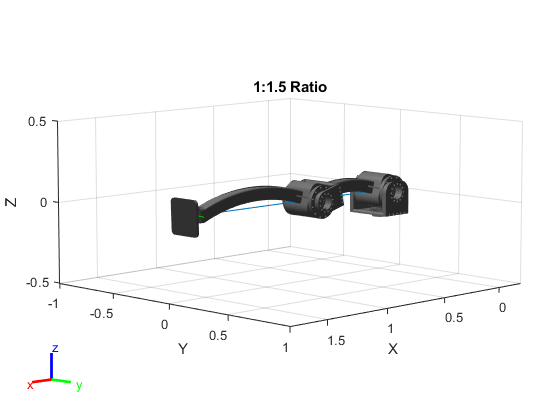

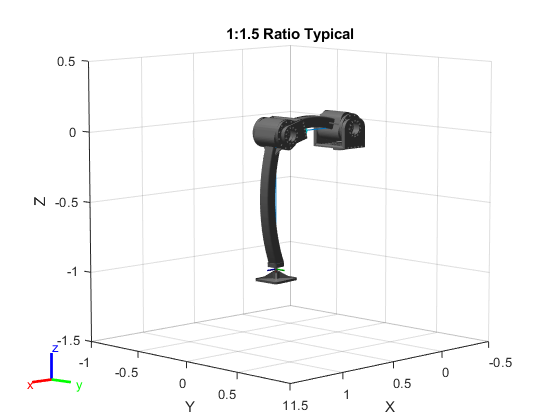

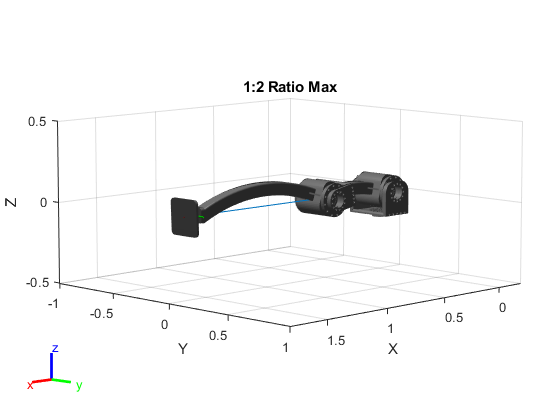

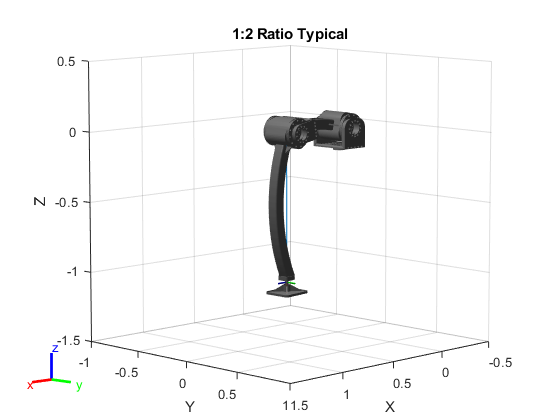

ratio_link = [0,    0.800,   0.800;
             0,    0.695,   0.905;
             0,    0.640,   0.960;
             0,    0.533,   1.067;
             0,    0.960,   0.640;
             0,    1.067,   0.533];

body2_mass = [39.9126, 39.4326, 39.1890, 38.7288, 40.6947, 41.2646];
body3_mass = [22.5262, 22.9799, 23.2205, 23.6938, 21.8466, 21.3998];

body2_com = [-0.3739, 0.0089, 0.0003;
            -0.3258, 0.0063, 0.0003;
            -0.3006, 0.0052, 0.0003;
            -0.2518, 0.0033, 0.0003;
            -0.4473, 0.0143, 0.0002;
            -0.4963, 0.0192, 0.0002];

body3_com = [-0.6529, 0.0041, 0.0047;
            -0.7365, 0.0041, 0.0068;
            -0.7799, 0.0040, 0.0081;
            -0.8633, 0.0040, 0.0112;
            -0.5233, 0.0042, 0.0024;
            -0.4356, 0.0043, 0.0013];

title_names_max = {'1:1 Ratio Max'; '1:1.3 Ratio Max'; '1:1.5 Ratio'; '1:2 Ratio Max'; '1.5:1 Ratio Max'; '2:1 Ratio Max'};
title_names_typical = {'1:1 Ratio Typical'; '1:1.3 Ratio Typical'; '1:1.5 Ratio Typical'; '1:2 Ratio Typical'; '1.5:1 Ratio Typical'; '2:1 Ratio Typical'};
link_names = ["Link_Two_800_L3Out.STL", "Link_Two_695_L3Out.STL", "Link_Two_640_L3Out.STL", "Link_Two_533_L3Out.STL", "Link_Two_960_L3Out.STL", "Link_Two_1067_L3Out.STL";
              "Link_Three_800_EEOut.STL", "Link_Three_905_EEOut.STL", "Link_Three_960_EEOut.STL", "Link_Three_1067_EEOut.STL", "Link_Three_640_EEOut.STL", "Link_Three_533_EEOut.STL"];
robot_count = length(ratio_link(:,1));

for i = 1:robot_count

    a = ratio_link(i,:);
    alpha = [pi/2 0 -pi/2];
    d = [0 0 0];
    theta = [0 0 0];
    DHparams = [a(1)      alpha(1)      d(1)   theta(1);
                a(2)      alpha(2)      d(2)   theta(2);
                a(3)      alpha(3)      d(3)   theta(3)];
    
    %Building The Robot by creating a rigid body tree
    leg = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use
    
    % Define the bodies and their joints
    body1 = robotics.RigidBody('Link_1'); %Create Link 1 of the robot.
    jnt1 = robotics.Joint('jnt1','revolute'); %Create a revolute joint.
    body2 = robotics.RigidBody('Link_2'); %Create Link 2 of the robot.
    jnt2 = robotics.Joint('jnt2','revolute'); %Create a revolute joint.
    body3 = robotics.RigidBody('Link_3'); %Create Link 3 of the robot.
    jnt3 = robotics.Joint('jnt3','revolute'); %Create a revolute joint.
    
    % Specify the body-to-body transformation using DH parameters
    setFixedTransform(jnt1,DHparams(1,:),'dh');
    setFixedTransform(jnt2,DHparams(2,:),'dh');
    setFixedTransform(jnt3,DHparams(3,:),'dh');
    
    % Specify the body joints
    body1.Joint = jnt1;
    body2.Joint = jnt2;
    body3.Joint = jnt3;
    
    % Specify the body mass
    body1.Mass = 26.6416;
    body2.Mass = body2_mass(i);
    body3.Mass = body3_mass(i);
    
    body1.CenterOfMass = [-0.0001, -0.0242, 0.0061];
    body2.CenterOfMass = body2_com(i,:);
    body3.CenterOfMass = body3_com(i,:);
    
    visual_name_body1 = "..\Robot CAD\STL\" + link_names(1,i);
    visual_name_body2 = "..\Robot CAD\STL\" + link_names(2,i);

    addVisual(body1, "Mesh", "..\Robot CAD\STL\Link_One_L2Out.STL");
    addVisual(body2, "Mesh", visual_name_body1);
    addVisual(body3, "Mesh", visual_name_body2);
    
    % Attach the Bodies
    addBody(leg,body1,'base')
    addBody(leg,body2,'Link_1');
    addBody(leg,body3,'Link_2');
    
    config = homeConfiguration(leg);
    leg.DataFormat = 'row';
    comLocation = centerOfMass(leg);
    str_x = "X: " + comLocation(1);
    str_y = "Y: " + comLocation(2);
    str_z = "Z: " + comLocation(3);
    str = {str_x, str_y, str_z};
    
    figure;
    show(leg);
    hold on
    scatter3(comLocation(1),comLocation(2),comLocation(3),'filled','MarkerFaceColor',[0 .75 .75])
    title(title_names_max(i))
    xlim([-.2 1.8])
    ylim([-1 1])
    zlim([-0.5 0.5])
    hold off
    
    leg.DataFormat = 'row';
    leg.Gravity = [0 0 -9.81];
    joints_tau_max(i,:) = inverseDynamics(leg);

    leg.DataFormat = 'struct';
    config = homeConfiguration(leg);
    config(3).JointPosition = -pi/2;
    figure;
    show(leg, config);
    hold on
    scatter3(comLocation(1),comLocation(2),comLocation(3),'filled','MarkerFaceColor',[0 .75 .75])
    title(title_names_typical(i))
    xlim([-.5 1.5])
    ylim([-1 1])
    zlim([-1.5 0.5])
    hold off

    leg.DataFormat = 'row';
    leg.Gravity = [0 0 -9.81];
    joints_tau_typical(i,:) = inverseDynamics(leg, [0,0,-pi/2]);
end

col_names = {'Joint 1 [N•m]', 'Joint 2 [N•m]', 'Joint 3 [N•m]'};
row_names = {'1:1 Ratio'; '1:1.3 Ratio'; '1:1.5 Ratio'; '1:2 Ratio'; '1.5:1 Ratio'; '2:1 Ratio'};
required_torque_max = table(joints_tau_max(:,1),joints_tau_max(:,2),joints_tau_max(:,3),'RowNames',row_names,'VariableNames',col_names)

required_torque_max = 6×3 table
                   Joint 1 [N•m]    Joint 2 [N•m]    Joint 3 [N•m]
                   _____________    _____________    _____________

    1:1 Ratio       -3.1554e-30        376.13           32.506    
    1:1.3 Ratio      3.1554e-30        337.48           37.985    
    1:1.5 Ratio      3.1554e-30        317.29           41.026    
    1:2 Ratio                 0        278.07           47.347    
    1.5:1 Ratio      3.1554e-30        435.43           25.011    
    2:1 Ratio                 0        475.47           20.447    


required_torque_typical = table(joints_tau_typical(:,1),joints_tau_typical(:,2),joints_tau_typical(:,3),'RowNames',row_names,'VariableNames',col_names)

required_torque_typical = 6×3 table
                   Joint 1 [N•m]    Joint 2 [N•m]    Joint 3 [N•m]
                   _____________    _____________    _____________

    1:1 Ratio                0         344.66            1.0386   
    1:1.3 Ratio              0         301.03            1.5329   
    1:1.5 Ratio     3.1554e-30         278.11            1.8451   
    1:2 Ratio                0         233.33            2.6033   
    1.5:1 Ratio     3.1554e-30         410.93           0.51436   
    2:1 Ratio       6.3109e-30         455.29           0.27291   


## Appendix

### DHparameters Function

This function calculates the rotation matrices based on a provided DHparameters table. By using a single row of a DH parameters table as the input you can generate the transformation matrix foran individual link. Each link's transformation matrix multiplied together would provide the same result as using the entire DH parameters table in this function.

DHparams = array of DH parameters in this format:


$$\textrm{DH}=\left\lbrack a\;\alpha \;d\;\theta \right\rbrack$$


function [T] = DHparameters(DHparams)
% Initializations
A_old = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; % Identity matrix for first iteration
rotation_count = length(DHparams(:,1));
for i = 1:rotation_count

    A_new = [cos(DHparams(i,4)) -sin(DHparams(i,4))*cos(DHparams(i,2))...
        sin(DHparams(i,4))*sin(DHparams(i,2)) DHparams(i,1)*cos(DHparams(i,4));...
        sin(DHparams(i,4)) cos(DHparams(i,4))*cos(DHparams(i,2))...
        -cos(DHparams(i,4))*sin(DHparams(i,2)) DHparams(i,1)*sin(DHparams(i,4));...
        0 sin(DHparams(i,2)) cos(DHparams(i,2)) DHparams(i,3);...
        0 0 0 1];

    A_old = A_old*A_new;
end
T = A_old;
end

### Compute Velocity Function

function vel = compute_velocity(p,q,dq)
    for i = 1:length(q)
        dpdq(:,i) = diff(p,q(i))*dq(i);
    end
    vel = simplify(expand(sum(dpdq,2)));
end

### Derivative Function

function dldq = derivative(l,q)
    for i = 1:length(q)
        dldq(:,i) = diff(l,q(i));
    end
    dldq = simplify(dldq);
end